#### *Load data*

close all
clear all
clc
path = 'Needs.mat';
load(path)

## Quick data exploration

We start looking at univariate distributions. For example, we check for imbalanced classes

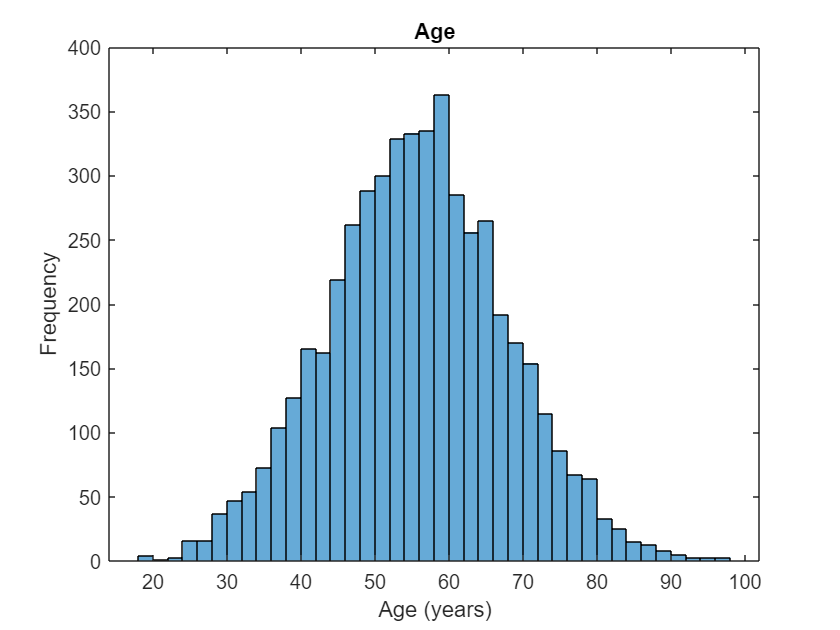

Data = Needs; % renaming

%age
figure
histogram(Data.Age)
title('Age')
xlabel('Age (years)')
ylabel('Frequency')

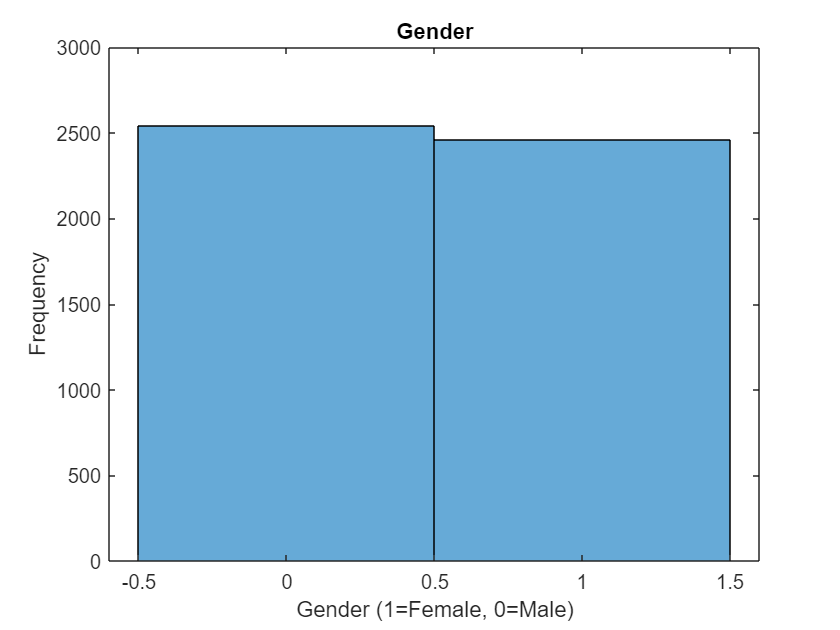

%Gender
figure
histogram(Data.Gender)
title('Gender')
xlabel('Gender (1=Female, 0=Male)')
ylabel('Frequency')

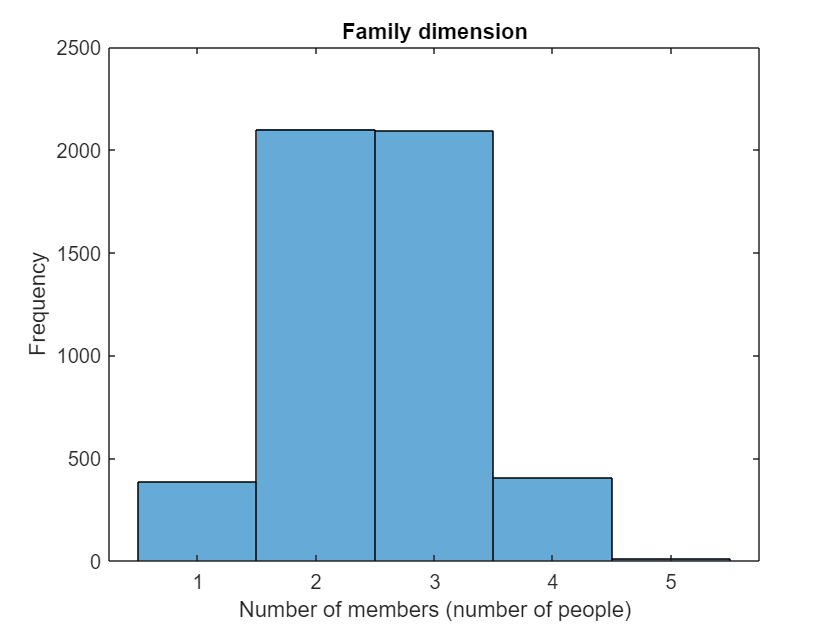

%Family dimension
figure
histogram(Data.FamilyMembers)
title('Family dimension')
xlabel('Number of members (number of people)')
ylabel('Frequency')

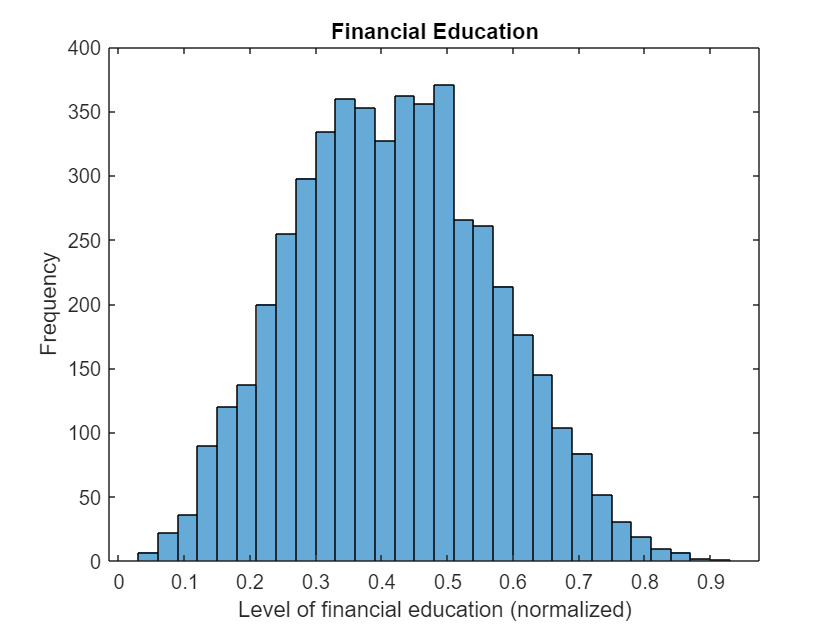

%Financial education
figure
histogram(Data.FinancialEducation)
title('Financial Education')
xlabel('Level of financial education (normalized)')
ylabel('Frequency')

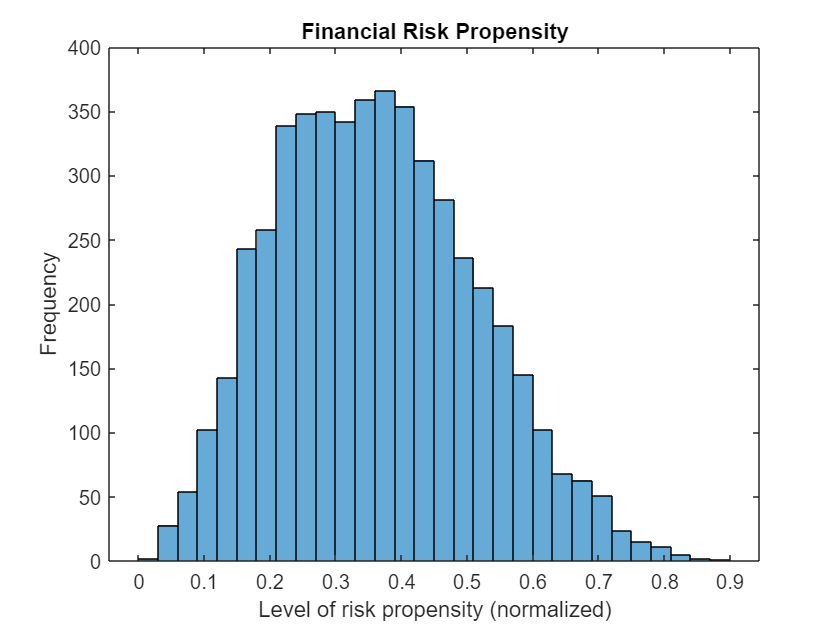

%Financial risk propensity
figure
histogram(Data.RiskPropensity)
title('Financial Risk Propensity')
xlabel('Level of risk propensity (normalized)')
ylabel('Frequency')

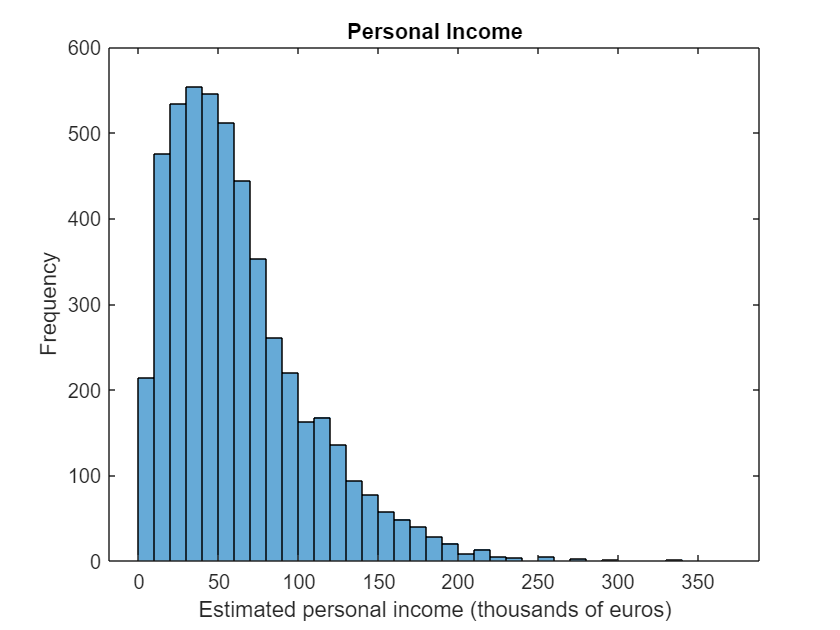

%income
figure
histogram(Data.Income)
title('Personal Income')
xlabel('Estimated personal income (thousands of euros)')
ylabel('Frequency')

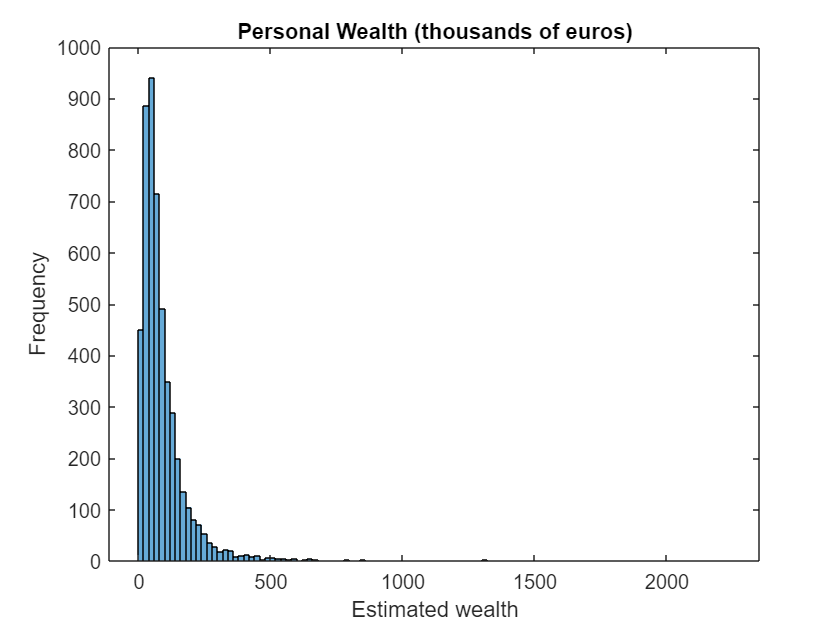

%wealth
figure
histogram(Data.Wealth)
title('Personal Wealth (thousands of euros)')
xlabel('Estimated wealth')
ylabel('Frequency')

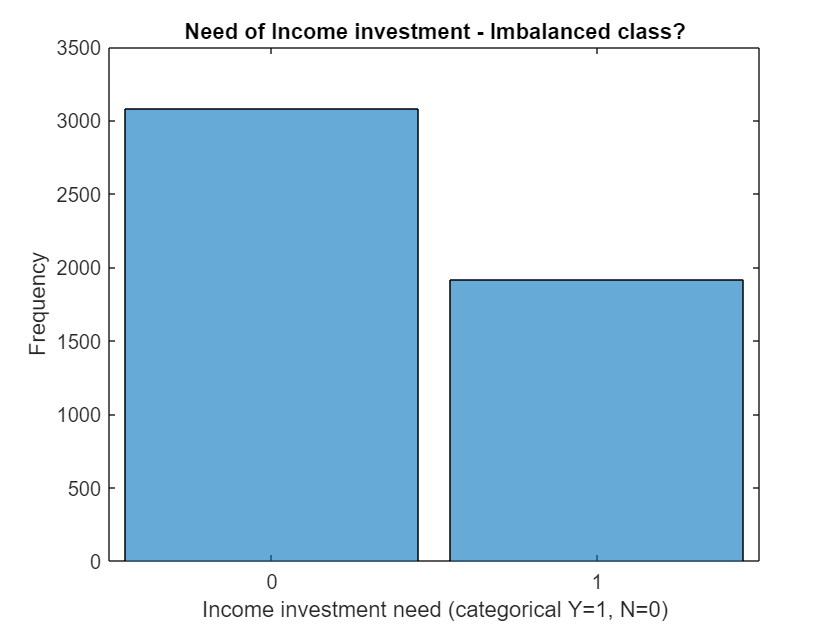

%Income investment
figure
histogram(Data.IncomeInvestment)
title('Need of Income investment - Imbalanced class?')
xlabel('Income investment need (categorical Y=1, N=0)')
ylabel('Frequency')

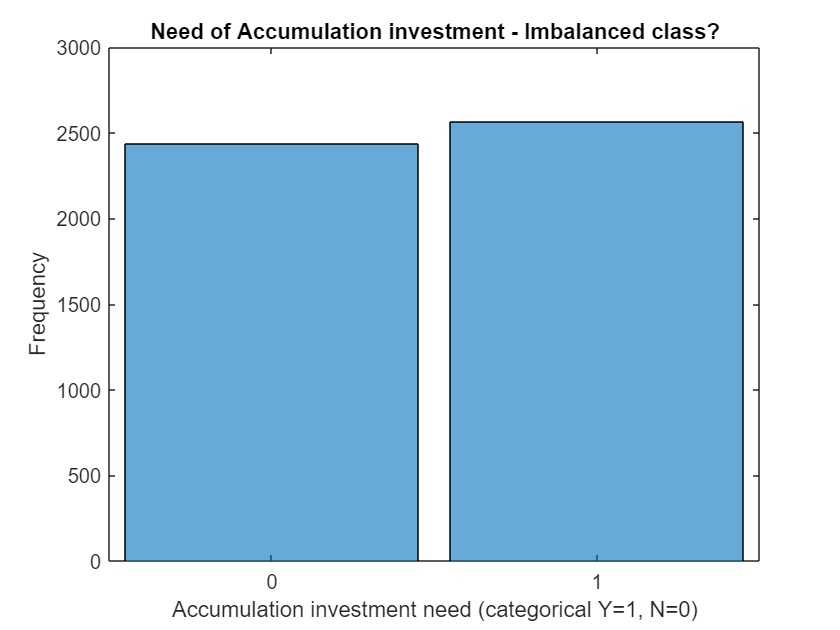

%Accumulation investment
figure
histogram(Data.AccumulationInvestment)
title('Need of Accumulation investment - Imbalanced class?')
xlabel('Accumulation investment need (categorical Y=1, N=0)')
ylabel('Frequency')

### Data transformation

Wealth and Income follow a power law, so we thought it better to use a log transformation and a boxcox transformation to make just a little bit extra nice.

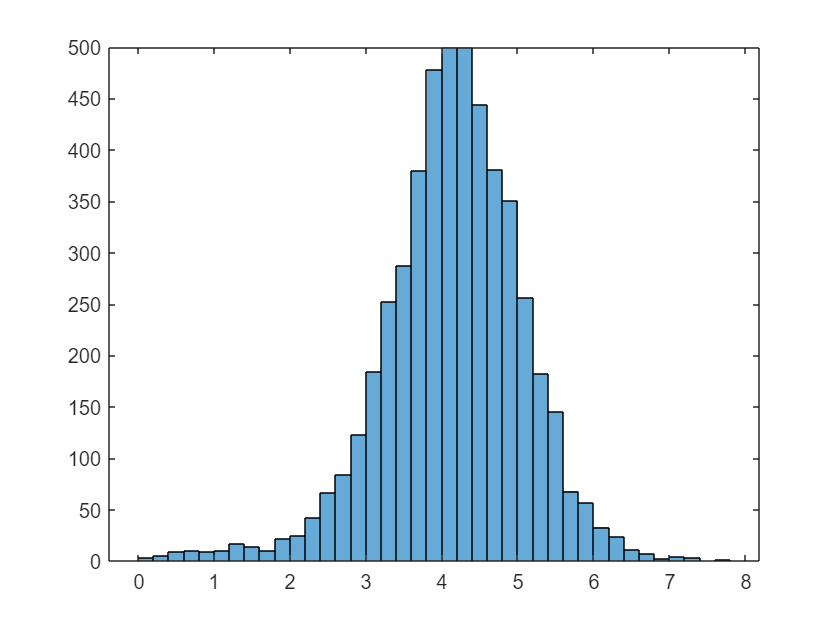

%wealth analysis
histogram(log(Data.Wealth)) % log transformation

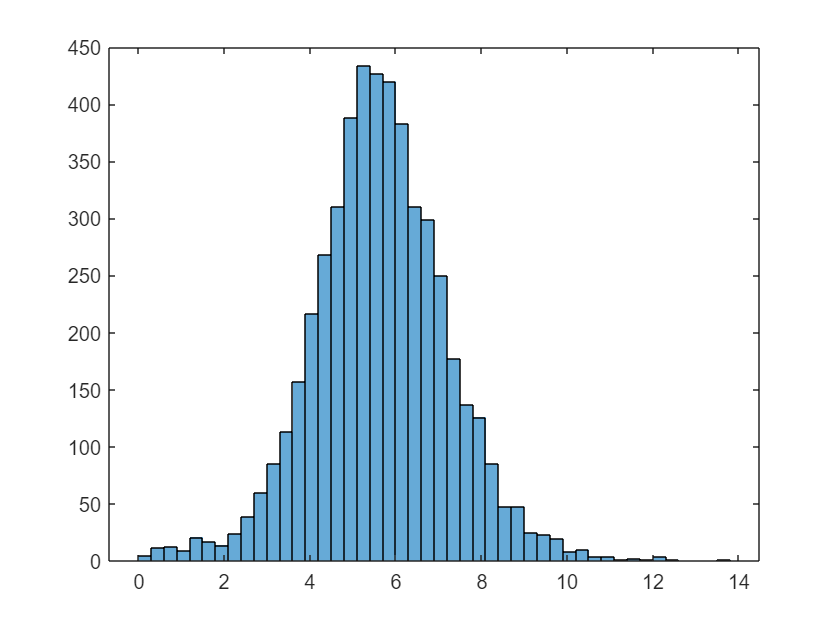

logWealth = log(Data.Wealth); % we'll go for the log-transformation
BoxWealth = boxcox(Data.Wealth);
histogram(BoxWealth); % Boxcox transformation

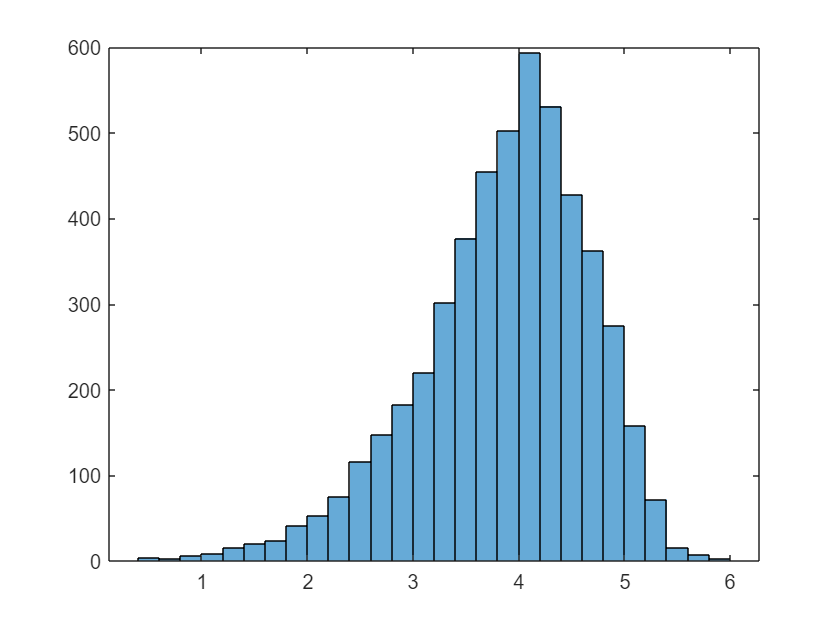

%income analysis
histogram(log(Data.Income)) % log transformation

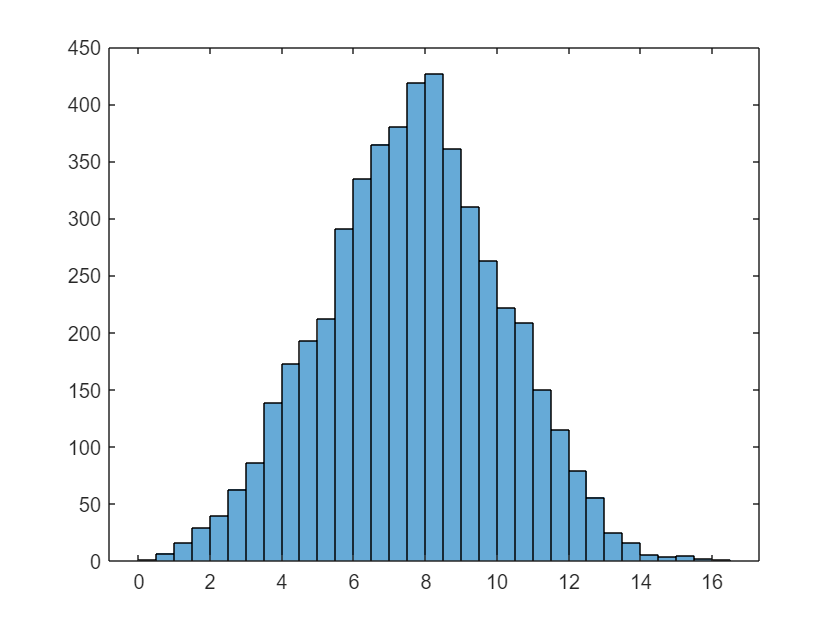

logIncome = log(Data.Income); % we'll go for the log transformation
BoxIncome = boxcox(Data.Income);
histogram(BoxIncome); % boxcox transformation

X =[zscore(Data.Age) Data.Gender zscore(Data.FamilyMembers) zscore(Data.FinancialEducation)...
    zscore(Data.RiskPropensity) zscore(BoxIncome) zscore(BoxWealth)];
Inc = [Data.IncomeInvestment];
Accum = [Data.AccumulationInvestment];
n = size(X,1);

We let the classification learner work with the whole Dataset X.

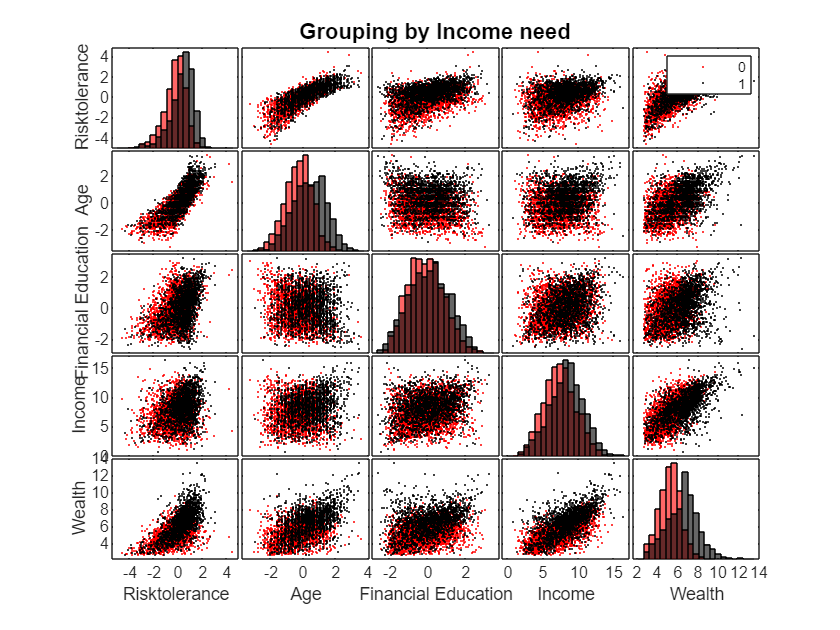

%take only wealthy data
wealthy = Data.Wealth>10;
SmallData = Data(wealthy,:);
%calculate the new feature risktolerance
Risktolerance = ( 0.6*zscore(SmallData.Age) + 0.3*zscore(SmallData.FinancialEducation) + 0.1*zscore(SmallData.RiskPropensity) ) ./ (logWealth(wealthy));
%create the new XSmall 
Xsmall = [zscore(Risktolerance) zscore(SmallData.Age) zscore(SmallData.FinancialEducation) BoxIncome(wealthy) BoxWealth(wealthy)];
%create the new Y for the smaller dataset
YsmallAcc = SmallData.AccumulationInvestment;
YsmallInc = SmallData.IncomeInvestment;
%gplot for the smaller dataset
%Income
figure
xnames = {'Risktolerance','Age', 'Financial Education', 'Income', 'Wealth'};
gplotmatrix(Xsmall,[],SmallData.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

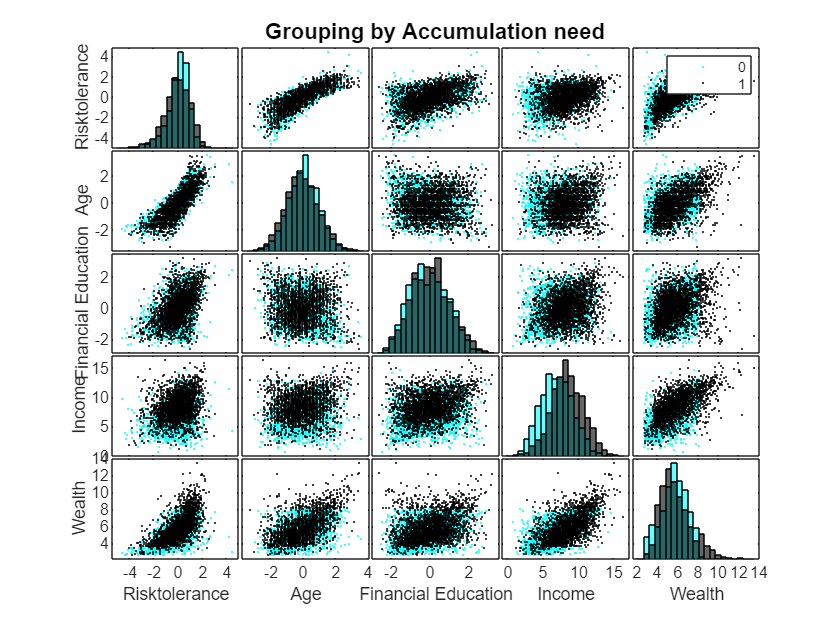

%Accumulation
figure
xnames = {'Risktolerance','Age', 'Financial Education', 'Income', 'Wealth'};
gplotmatrix(Xsmall,[],SmallData.AccumulationInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

Now we let the classification learner work on this new dataset XSmall and its new feature RiskTolerance.

**Recommending products**

**!!! Here we have to decide which labels we are going to use**

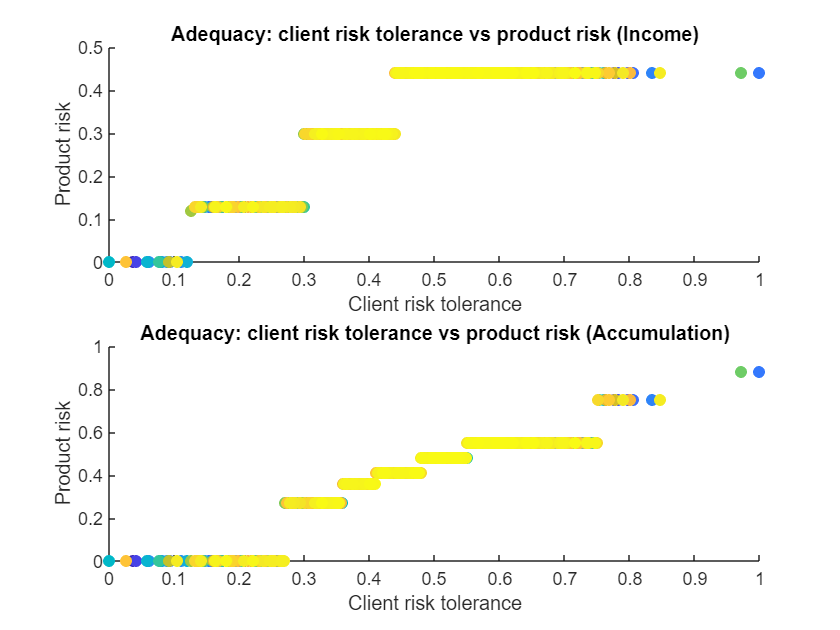

%rescale RiskTolerance in the [0,1] range
Risktolerance = rescale(Risktolerance);

%retrieving the client IDs and Risktolerance
Client_ID = SmallData.ID;
ClientRisktolerance = rescale(Xsmall(:,1));

%load the models to calculate the Accumulation and Income Investments 
load("Models/SmallAccModel.mat");
load("Models/SmallIncModel.mat");

%predict whether or not the client want Accumulation or Income
[yfitInc,scores] = SmallIncModel.predictFcn(Xsmall);
yfitInc = cast(yfitInc, "uint16");
[yfitAcc,scores] = SmallAccModel.predictFcn(Xsmall);
yfitAcc = cast(yfitAcc, "uint16");

%create the variables for income products
IncomeProducts = Products(Products.Type == 0,:);
minRiskInc = min(IncomeProducts.Risk);
product_IDInc = cast(IncomeProducts.ID, "uint16")-1;

%create the variables for accumulation products
AccumulationProducts = Products(Products.Type == 1,:);
minRiskAcc = min(AccumulationProducts.Risk);
product_IDAcc = cast(AccumulationProducts.ID, "uint16")-1;

%create vector to save recommendations
NBA_IDProduct = zeros(size(Xsmall,1),2);
RecommendedRiskLevel = zeros(size(Xsmall,1),2);

%we match the client with their reccommended products
for i = 1:size(Client_ID,1)
    tolerance = ClientRisktolerance(i);
    %if labeled for Income and tolerance is equal or greater than the
    %minimum risk
    if yfitInc(i) && tolerance>=minRiskInc
        %find suitable income product with highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk <= tolerance));
        NBA_IDProduct(i,1) = product_IDInc(IncomeProducts.Risk==M);
        RecommendedRiskLevel(i,1) = M;
    end
    if yfitAcc(i) && tolerance>=minRiskAcc
        %find suitable income product with highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk <= tolerance));
        NBA_IDProduct(i,2) = product_IDAcc(AccumulationProducts.Risk==M);
        RecommendedRiskLevel(i,2) = M;
    end
end

% recommendations
%NBA = [Client_ID NBA_IDProduct(:,1) NBA_IDProduct(:,2)];

figure
c = linspace(0,1,length(ClientRisktolerance));
subplot(2,1,1)
scatter(ClientRisktolerance, RecommendedRiskLevel(:,1), [], c, 'filled')
title('Adequacy: client risk tolerance vs product risk (Income)')
xlabel('Client risk tolerance')
ylabel('Product risk')
subplot(2,1,2)
scatter(ClientRisktolerance, RecommendedRiskLevel(:,2), [], c, 'filled')
title('Adequacy: client risk tolerance vs product risk (Accumulation)')
xlabel('Client risk tolerance')
ylabel('Product risk')